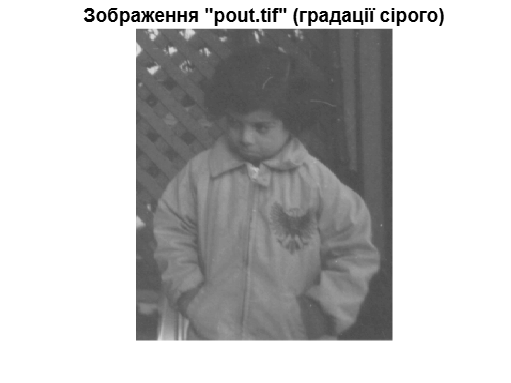

clear;
close all;

% Завантаження вбудованих зображень з Image Processing Toolbox
I1 = imread('pout.tif');       % Приклад градацій сірого
I2 = imread('peppers.png');    % Приклад кольорового зображення (RGB)

% Відображення першого зображення
figure;
imshow(I1);
title('Зображення "pout.tif" (градації сірого)');

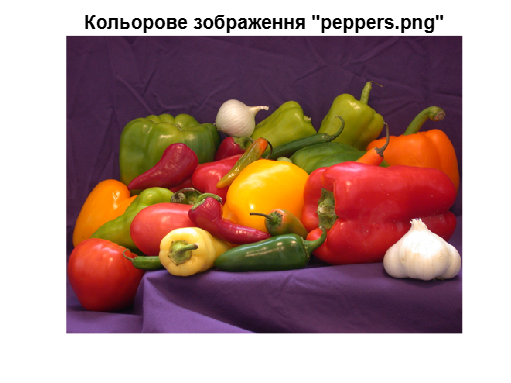


% Відображення другого зображення в новому вікні
figure;
imshow(I2);
title('Кольорове зображення "peppers.png"');


% Розмір зображення pout.tif
disp('Розмір pout.tif:');

Розмір pout.tif:


size(I1)

ans =    291   240



% Детальна інформація про зображення peppers.png
disp('Інформація про peppers.png:');

Інформація про peppers.png:


whos I2

  Name        Size                Bytes  Class    Attributes

  I2        384x512x3            589824  uint8              



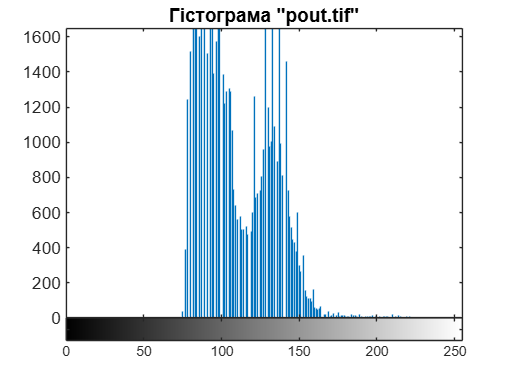


% Збереження зображення у теку MATLAB Drive (онлайн)
imwrite(I1, '/MATLAB Drive/pout_processed.jpg');
imwrite(I2, '/MATLAB Drive/peppers_processed.png');

% Гістограма для градацій сірого
figure;
imhist(I1);
title('Гістограма "pout.tif"');

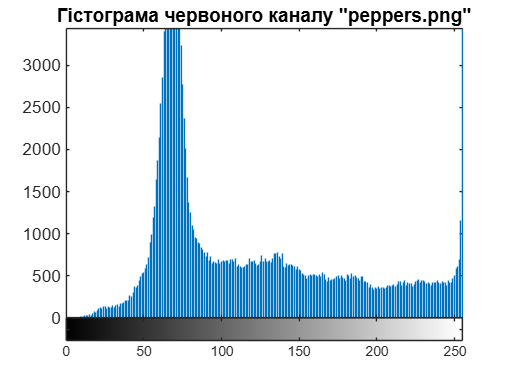


% Гістограма для кольорового зображення (червоний канал)
figure;
imhist(I2(:,:,1)); % Червоний канал
title('Гістограма червоного каналу "peppers.png"');

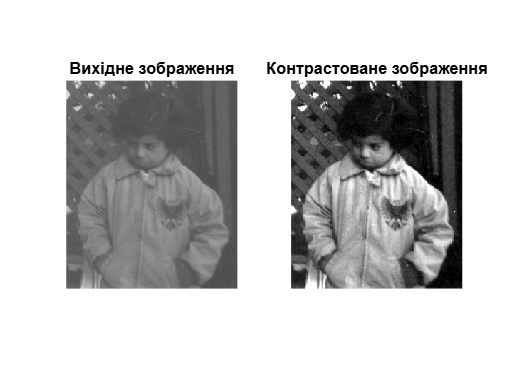


% Лінійне контрастування для pout.tif
I1_adjusted = imadjust(I1);

% Відображення результатів
figure;
subplot(1,2,1);
imshow(I1);
title('Вихідне зображення');
subplot(1,2,2);
imshow(I1_adjusted);
title('Контрастоване зображення');

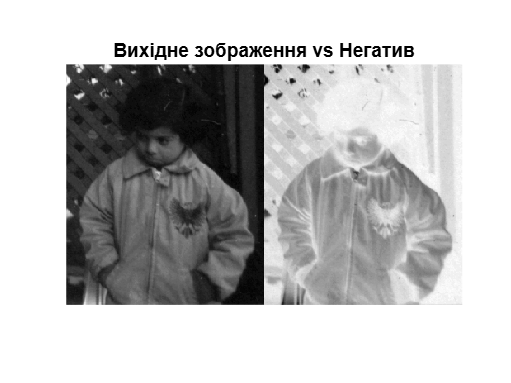


% Створення негативу для pout.tif
I1_neg = imcomplement(I1);

% Відображення
figure;
imshowpair(I1, I1_neg, 'montage');
title('Вихідне зображення vs Негатив');